## **Soft beam free fall** 

We created a 0.5m soft beam with radius linearly varying from 2cm to 1cm.

Torsion (x-axis) and bending (y- and z-axis) modes of deformation are enabled with a cubic strain.

SorosimLink (`L1`) and SorosimLinkage (`T1`) saved in `FreeFall.mat`

load('FreeFall.mat')

To see the properties of `L1`

L1

L1 =   SorosimLink with properties:

    jointtype: 'N'
     linktype: 's'
           CS: 'C'
         npie: 2
           lp: {[0.5000]}
            L: 0.5000
            r: {@(X1)X1.*(-1.0./1.0e+2)+1.0./5.0e+1}
            h: {[]}
            w: {[]}
            a: {[]}
            b: {[]}
           gi: {[4×4 double]}
           gf: {[4×4 double]}
            E: 1000000
          Poi: 0.5000
            G: 3.3333e+05
          Eta: 10000
          Rho: 1000
           Kj: []
           Dj: []
            M: []
          n_l: 25
          n_r: 18
        color: [0.7922 0.9595 0.6557]
          CPF: 0
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: 0.0856


To see the properties of S`1`

T1

T1 =   SorosimLinkage with properties:

                   N: 1
                ndof: 8
                nsig: 8
              VLinks: [1×1 SorosimLink]
           LinkIndex: 1
            CVTwists: {[1×2 SorosimTwist]}
               iLpre: 0
               g_ini: [4×4 double]
             Z_order: 4
                nCLj: []
                iACL: []
                iCLB: []
          VTwistsCLj: []
               gACLj: []
               gBCLj: []
        CLprecompute: [1×1 struct]
                T_BS: []
             Gravity: 1
                   G: [6×1 double]
          PointForce: 0
       FollowerForce: []
                  np: []
              Fp_loc: []
              Fp_vec: []
                CEFP: 0
             M_added: []
            Actuated: 0
                nact: 0
                Bqj1: []
              n_jact: 0
              i_jact: []
             i_jactq: []
    WrenchControlled: []
             

To see the problem definition:

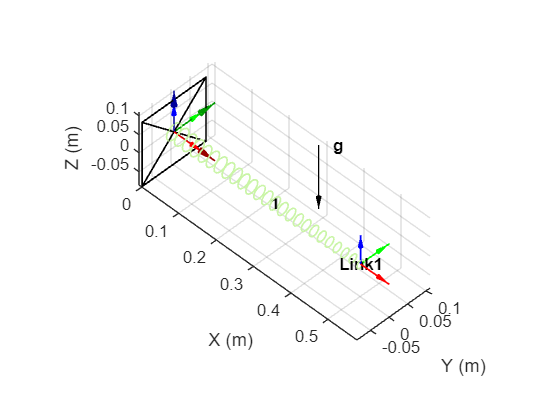

T1.plotq0

The result should be:

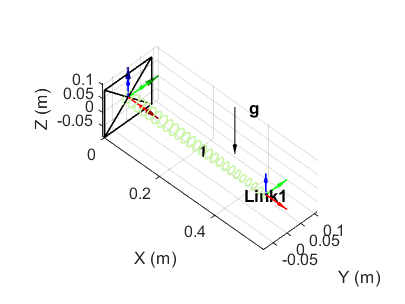

The beam is rigidly fixed at one end and subjected to gravity.

### **Static equilibirum analysis**

For statics equilibirum analysis type:

Time-advancing

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          9         4.48175e+12                        2.18e+12              1
     1         18         5.45211e+11              1         1.09e+12              1
     2         27         1.24186e+10            2.5         8.47e+10            2.5
     3         36         4.10842e+06        1.29034         3.57e+09           6.25
     4         45           0.0489505      0.0102152         3.89e+05           6.25
     5         54         1.25138e-15    5.34177e-07           0.0556           6.25
     6         63          7.5841e-19    5.15782e-12           0.0013           6.25

Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the value
of the 

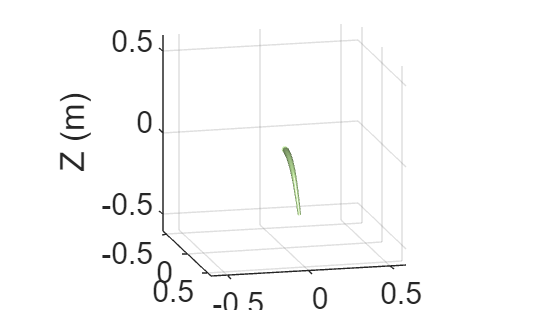

q=T1.statics;

A dialog box will pop up, asking for the initial guess. The user can choose the default value.

The equilibirum solution is,

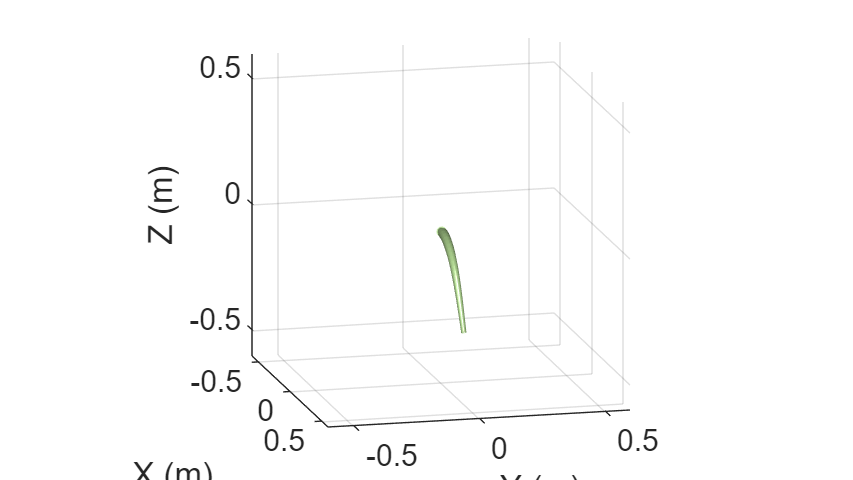

### **Damped dynamics**

For dynamics problem, type:

    0.0155

    0.3968

    1.0610

    2.0349

    3.8203

Elapsed time is 1.798886 seconds.


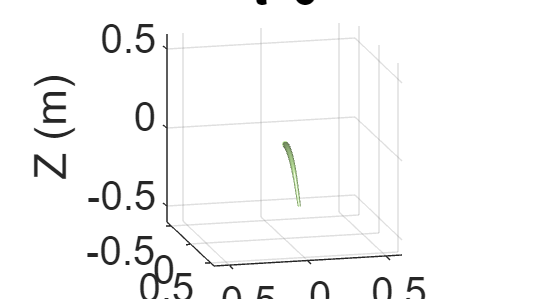

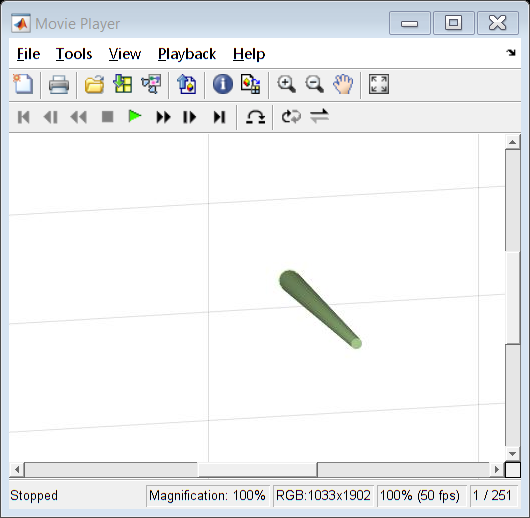

[t,qqd]=T1.dynamics([],'ode15s');

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

Another dialog box will appear, asking the user if he/she wants to see a plot during the dynamic compulation. (this is slow and will not work in live script)

Dynamic compulation will take some time.

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will also take some time. 

A video named `Dynamics.avi` will be saved in the folder.

Energy computations can be made by running energy.m after the dynamic simulation is complete

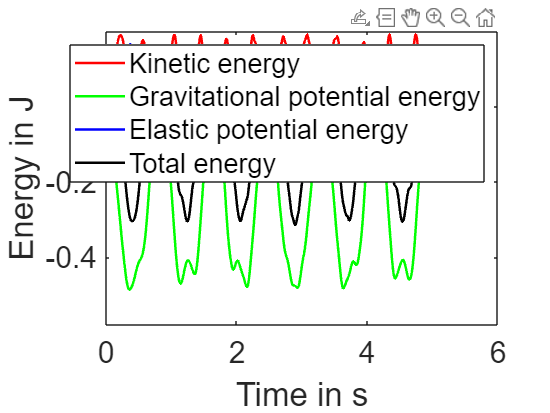

energy

### **Undamped dynamics**

To turn off the elastic damping of the system type:

T1.Damped=false;

We run the dynamic simulation again

    0.0840

    0.3543

    0.5739

    0.8256

    1.1298

    1.4043

    1.7096

    1.9967

    2.2981

    2.6279

    2.8974

    3.2518

    3.5451

    3.9880

    4.7776

Elapsed time is 3.256943 seconds.


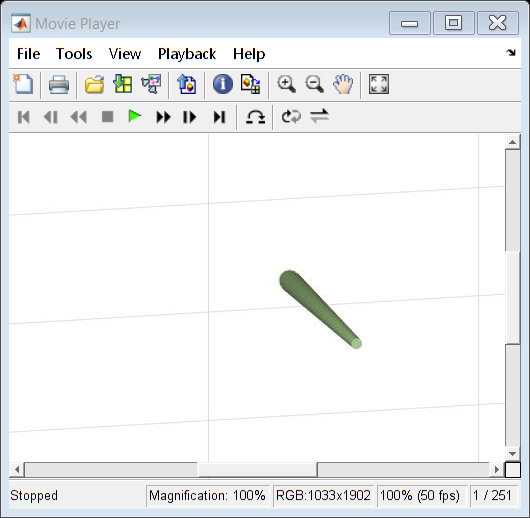

[t,qqd]=T1.dynamics([],'ode113');

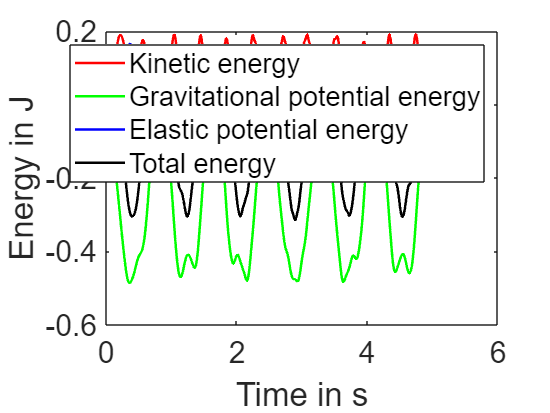

energy